Ripley dataset

load ripley.mat

Visualize the data. Inspect the data structure: what seems to be important prop-

erties of the data?

2 inputs , binary classification 

 Which classi�cation model do you think you need, based on the

complexity of the data?

linear, RBF 

## Visualize the training data

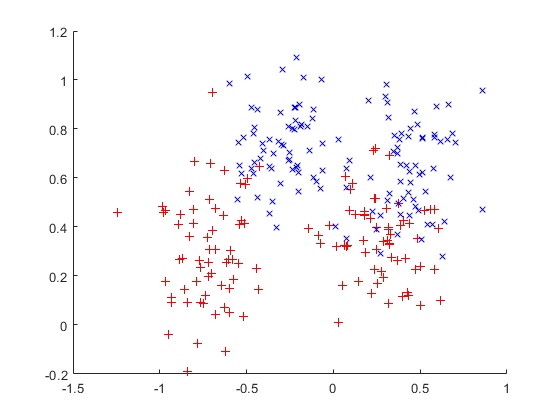

figure 
hold on;
plot(Xtrain(1:125,1), Xtrain(1:125,2), 'r+');
plot(Xtrain(126:250,1), Xtrain(126:250,2), 'bx');

## Visualize the test data

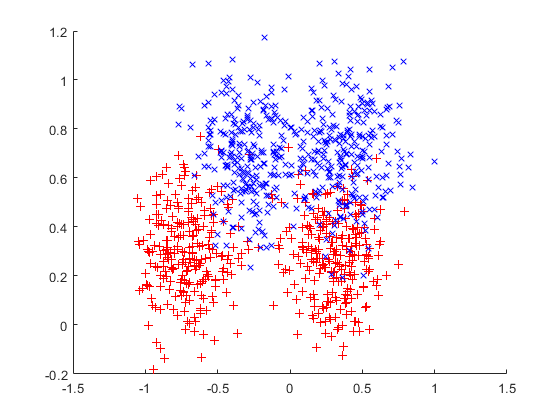

figure 
hold on;
plot(Xtest(1:500,1), Xtest(1:500,2), 'r+');
plot(Xtest(501:1000,1), Xtest(501:1000,2), 'bx');

## Linear model

Try out different models (linear, polynomial, RBF kernel) with tuned hyperparameter

and kernel parameters. Compute the ROC curves. Which model performs best?

Which model would you choose?

Define the model parameters

type = 'c';
kernel_type = 'lin_kernel';

model = {Xtrain,Ytrain,type,[],[],kernel_type};

model = 1×6 cell array
    {250×2 double}    {250×1 double}    {'c'}    {0×0 double}    {0×0 double}    {'lin_kernel'}


Tuning the parameter

gam = tunelssvm(model,'simplex','leaveoneoutlssvm', {'misclass'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.0028391
                                          F(X)=         0.14
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  leaveoneoutlssvm
    kernel function                 lin_kernel
 

 3. starting value:                   0.0028391

 Iteration   Func-count    min f(x)    log(gamma)      Procedure

     1           2     1.400000e-01     -5.8643           initial 
     2           5     1.400000e-01     -5.8643           shrink 
     3           7     1.400000e-01     -5.8643           contract inside 
     4           9     1.400000e-01     -5.8643           contract inside 
optimisation terminated sucessfully (TolFun criterion)

Simplex results: 
X=0.002839  , F(X)=1.400000e

Compute the ROC curves

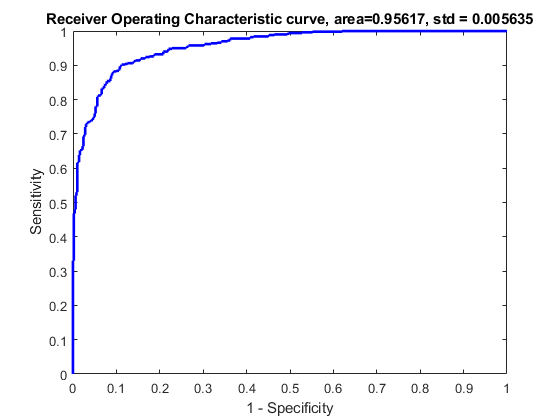

[alpha, b] = trainlssvm({ Xtrain , Ytrain , 'c', gam, [],'lin_kernel'});
[Yest, Ylatent] = simlssvm({ Xtrain , Ytrain , 'c', gam, [],'lin_kernel'},{alpha, b},Xtest);
figure Name 'ROC Linear Kernel'
roc(Ylatent, Ytest);

## Polynomial model

Define the model parameters

type = 'c';
kernel_type = 'poly_kernel';

model = {Xtrain,Ytrain,type,[],[],kernel_type};


Tuning the parameter

[gam,sig2] = tunelssvm(model,'simplex','crossvalidatelssvm', {10, 'misclass'});


   Determine initial hyperparameters for simplex...
  |-                                              -|
  **************************************************

 1. Simulated Annealing results:          [gam]         2087.5019
                                          [t]           1.1712
                                          [degree]      7
                                          F(X)=         0.128
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 poly_kernel
 

 3. starting values:                   2087.5019      1.1712154              7

 Iteration   Func-count    min f(x)    log(gamma)      log(t)        Procedure

     1           3     1.280000e-01     8.8437         0.1580         initial   
     2           5     1.280000e-01     8.8437         0.1580         contract inside   
optimisation terminated sucessfully (TolFun criterion)

Simplex results: 


Compute the ROC curves

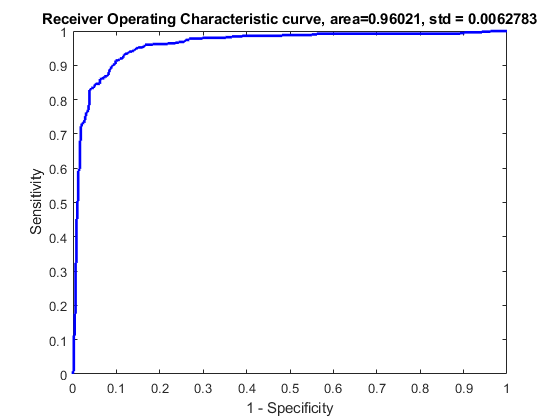

[alpha, b] = trainlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'poly_kernel'});
[Yest, Ylatent] = simlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'poly_kernel'},{alpha, b},Xtest);
figure Name 'ROC Poly Kernel'
roc(Ylatent, Ytest);

## RBF model

Define the model parameters

type = 'c';
kernel_type = 'RBF_kernel';

model = {Xtrain,Ytrain,type,[],[],kernel_type};


Tuning the parameter

[gam,sig2] = tunelssvm(model,'simplex','crossvalidatelssvm', {10, 'misclass'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.7994
                                          [sig2]        0.41083
                                          F(X)=         0.108
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.7994     0.41083

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     1.080000e-01     0.5875        -0.8896      initial 
     2           7     1.080000e-01     0.5875        -0.8896      shrink 
     3          11     1.080000e-01     0.5875        -0.8896      shrink 
     4          13     1.080000e-01     0.5875        -0.8896      contrac

Compute the ROC curves

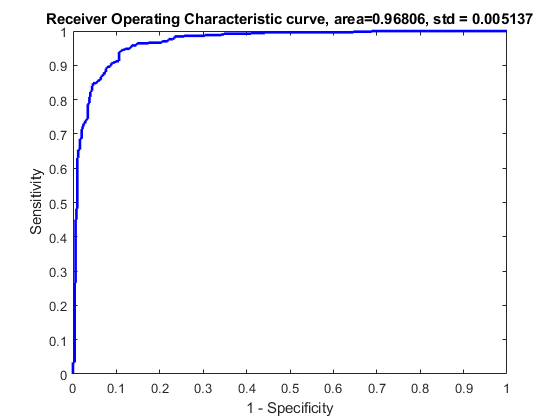

[alpha, b] = trainlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'RBF_kernel'});
[Yest, Ylatent] = simlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'RBF_kernel'},{alpha, b},Xtest);
figure Name 'ROC Poly Kernel'
roc(Ylatent, Ytest);